%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                         %
%                   LAB 1 - ASEN 2004                     %
%                 Glider Wing Analysis                    %
%                                                         %
%                                                         %
%        This script takes in 2-dimensional data for      %
%            a foam glider and calculates                 %
%        the 3-dimensional whole aircraft drag polar,     %
%        as well as performance analysis calculations     %
%       for maximum glide range, maximum powered range,   %
%             and maximum powered endurance.              %
%                                                         %
%                  Created: 02/03/2021                    %
%               Last Modified: 02/09/2021                 %
%                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Set Environment

clear
clc
close all

## Declare and Define the Braced Glider Variables

Re = 160000;                % Glider Reynold's Number [dimensionless]
e0 = 0.601;                 % Glider Oswald's Efficiency 
C_fe = 0.003;              % Civil Transport Skin Friction Coefficient
b = .85;                      % Glider Wing Span [m^2]
edgeC = 0.15;
baseC = 0.15;
S_ref = b * (edgeC + baseC);      % Glider Reference Planform Area [m]
AR = b^2/(S_ref);             % Glider Aspect Ratio [dimensionless]
winglets = 4 * ((0.075) - (0.00635 * 2)) * edgeC;
fusalage = 4 * ((0.075) * (0.75)) + 2 * (0.075)^2;
vertStab = 2*((0.07 + 0.07)/2)*0.15;
S_wet = winglets + fusalage + 2 * (S_ref) + vertStab;            % Glider Wet Planform Area [m^2]
d = 0.075;                  % Glider Fuselage Diameter [m]
W_max = 6.05;                   % Glider max possible weight [N]
W = 1.5696 + (S_wet * 0.295 * 9.81);
h = 7;                      % Glider launch altitude [m]
rho = 1.0581;               % Air density STD ATM for Boulder [kg/m^3]

% Create the Variable Array for the Tempest
vars = [AR, Re, e0, S_wet, S_ref, C_fe, d, b];

% Appendix Two Tables
% [AOA C_l C_d C_M]
dataAct = [-15 -0.6  0.2  0.09;
         -14 -0.6  0.2  0.09; 
         -13 -0.7  0.2  0.09;
         -12 -0.8  0.19 0.085;
         -11 -0.8  0.18 0.08;
         -10 -0.75 0.14 0.07;
         -9  -0.85 0.12 0.055;
         -8  -0.8  0.1  0.04;
         -7  -0.7  0.08 0.03;
         -6  -0.6  0.06 0;
         -5  -0.5  0.04 -0.01;
         -4  -0.4  0.02 -0.005;
         -3  -0.3  0.01 0;
         -2  -0.2  0.005 0;
         -1  -0.1  0.005 0;
         0   0     0     0;
         1   0.1   0     0;
         2   0.2   0.005 0;
         3   0.3   0.01  0;
         4   0.4   0.02  0;
         5   0.45  0.04  0;
         6   0.6   0.06  0;
         7   0.7   0.08  -0.01;
         8   0.8   0.12  -0.03;
         9   0.8   0.13  -0.06;
         10  0.8   0.14  -0.08;
         11  0.8   0.16  -0.1;
         12  0.8   0.18  -0.1;
         13  0.8   0.19  -0.1;
         14  0.74  0.21  -0.1;
         15  0.74  0.22  -0.1;
         16  0.74  0.24  -0.1;
         17  0.73  0.25  -0.1;
         18  0.73  0.26  -0.1;
         19  0.7   0.28  -0.1;
         20  0.7   0.3   -0.1;];

## Calculations

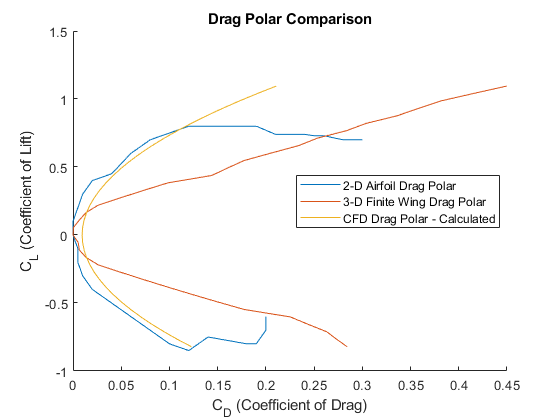

% Calculate the C_L and C_D 
[C_L,C_D_w] = finiteWingLift(dataAct,vars,0,6);

% Calculate the Whole Drag Polar using labDocument method
eLabDocument = labDocument(vars);
[C_D_labDocument,C_D_0_labDocument] = wholeAircraftDragPolar(C_L, C_D_w, eLabDocument, vars);

% Calculate the Whole Drag Polar using MNita_DScholz method
eMNita_DScholz = MNita_DScholz(C_D_w, 0.9, vars);
[C_D_MNita_DScholz,C_D_0_MNita_DScholz] = wholeAircraftDragPolar(C_L, C_D_w, eMNita_DScholz, vars);

% Calculate the Whole Drag Polar using Oberts method
eOberts = oberts(vars);
[C_D_Oberts,C_D_0_Oberts] = wholeAircraftDragPolar(C_L, C_D_w, eOberts, vars);

% Calculate the Whole Drag Polar using Kroo's method
eKroos = kroos(C_D_w, 0.9, vars);
[C_D_Kroos,C_D_0_Kroos] = wholeAircraftDragPolar(C_L, C_D_w, eKroos, vars);

% Combine all Oswald's factors and C_Ds in one array for performance calcs
e0 = [eKroos,eLabDocument,eMNita_DScholz,eOberts];
C_D = [C_D_Kroos,C_D_labDocument,C_D_MNita_DScholz,C_D_Oberts];
C_D_0 = mean([C_D_0_Oberts,C_D_0_labDocument,C_D_0_MNita_DScholz,C_D_0_Kroos]);

% figure;
% hold on
% plot(data(:,1), C_L);
% plot(data(:,1), data(:,2));
% plot(dataAct(:,1), dataAct(:,2),'-.r*');
% title('Lift Curve Comparsion: Tempest UAS');
% xlabel('α (Angle of Attack)');
% ylabel('C_L (Coefficient of Lift)');
% legend('3-D Finite Wing Curve', '2-D Airfoil Curve', 'Tempest CFD Drag Polar', 'Location', 'best');
% hold off

figure;
hold on
plot(dataAct(:,3), dataAct(:,2));
plot(C_D_w,C_L);
plot(C_D_MNita_DScholz,C_L);
title('Drag Polar Comparison');
ylabel('C_L (Coefficient of Lift)');
xlabel('C_D (Coefficient of Drag)');
legend('2-D Airfoil Drag Polar','3-D Finite Wing Drag Polar','CFD Drag Polar - Calculated','Location','best');
hold off

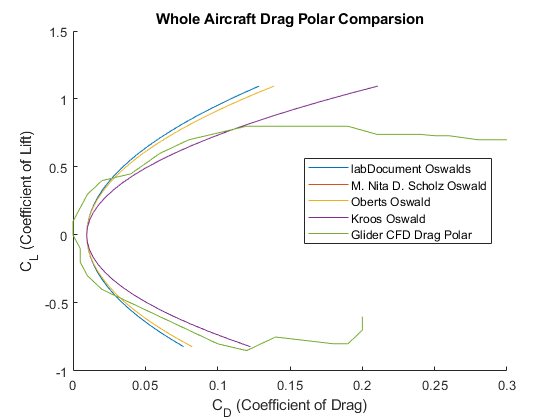


figure;
hold on
plot(C_D_labDocument,C_L);
plot(C_D_MNita_DScholz,C_L);
plot(C_D_Oberts,C_L);
plot(C_D_Kroos,C_L);
plot(dataAct(:,3),dataAct(:,2));
title('Whole Aircraft Drag Polar Comparsion');
xlabel('C_D (Coefficient of Drag)');
ylabel('C_L (Coefficient of Lift)');
legend('labDocument Oswalds', ...
       'M. Nita D. Scholz Oswald', ...
       'Oberts Oswald', ...
       'Kroos Oswald', 'Glider CFD Drag Polar', 'Location', 'best');
hold off

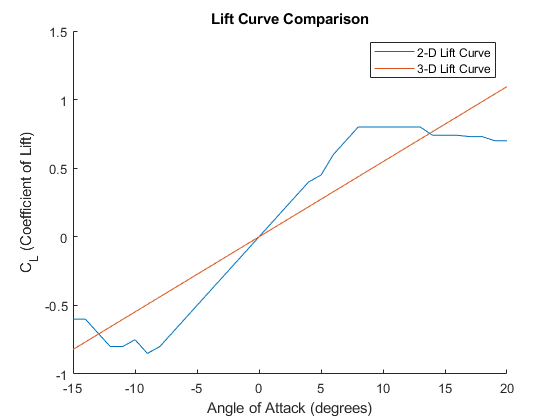


figure;
hold on
plot(dataAct(:,1),dataAct(:,2));
plot(dataAct(:,1),C_L);
title('Lift Curve Comparison');
xlabel('Angle of Attack (degrees)');
ylabel('C_L (Coefficient of Lift)');
legend('2-D Lift Curve','3-D Lift Curve');
hold off

## Performace Flight Conditions Calculations

% Define empty arrays for glide LDmaxes
Glide_LDMax = zeros(1,4);

% Define empty arrays for max glide ranges, endurances, angles and velocities
Glide_Range_V = zeros(1,4);
Glide_Theta = zeros(1,4);
Glide_Range = zeros(1,4);
Glide_Endurance = zeros(1,4);

% performance calculations for each Oswald's using calculated data
for i=1:4
   [Glide_LDMax(i),Glide_Range_V(i),Glide_Theta(i),...
       Glide_Range(i),Glide_Endurance(i)] = ...
       glide(h,C_D(:,i),C_L,e0(i),...
       AR,rho,W,S_ref,C_D_0); 
end

% Tempest performance calculations for avg Oswald's using given data
[FiniteGlide_LDMax,FiniteGlide_Range_V,FiniteGlide_Theta,...
    FiniteGlide_Range,FiniteEndurance] = ...
    glide(h,dataAct(:,3),dataAct(:,2),mean(e0),...
    AR,rho,W,S_ref,C_D_0);

## Print results out to terminal

Results = table([Glide_LDMax';mean(Glide_LDMax);FiniteGlide_LDMax],...
    [Glide_Range_V';mean(Glide_Range_V);FiniteGlide_Range_V],...
    [Glide_Theta';mean(Glide_Theta);FiniteGlide_Theta],...
    [Glide_Range';mean(Glide_Range);FiniteGlide_Range],...
    [Glide_Endurance';mean(Glide_Endurance);FiniteEndurance],...
    'RowNames',{'Kroos','Lab Doc','Scholz','Oberts','Mean','2D'},...
    'VariableNames',{'Glide LDMax','Glide Max Range Velocity (m/s)',...
    'Glide AoA (deg)','Max Glide Range (m)','Glide Endurance (s)'})

Results = 6×5 table
               Glide LDMax    Glide Max Range Velocity (m/s)    Glide AoA (deg)    Max Glide Range (m)    Glide Endurance (s)
               ___________    ______________________________    _______________    ___________________    ___________________

    Kroos        12.502                   11.422                    4.5732               87.514                 7.6863       
    Lab Doc      16.273                   10.025                    3.5165               113.91                 11.384       
    Scholz       12.502                   11.422                    4.5732               87.514                 7.6863       
    Oberts        15.59                   10.236                    3.6702               109.13                

## Functions

% finiteWingLift
%
% Function that calculates the 3D finite wing 3D lift coefficient and 3D wing
% drag polar
%
% @param data   The table data that includes the AOA, C_l, and the C_d in
%                   that order.
% @param vars   Needed variables on a per aircraft process like Aspect ratio
%                   and oswald's number
% @param aoa_one The lowest AOA to evaluate at
% @param aoa_two The highest AOA to evaluate at
%

function [C_L,C_D_wing] = finiteWingLift(data,vars,aoa_one,aoa_two)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Get the slope of the linear portion of the 2D lift curve from airfoil data
    linearFit = polyfit(data(data(data(:,1)<aoa_two,1)>aoa_one,1),data(data(data(:,1)<aoa_two,1)>aoa_one,2),1);
    
    % Set the slope of 2D airfoil curve as a_0 according to convention
    a_0 = linearFit(1);
    
    % Define the Span Efficiency factor
    e = 0.9;
    
    % Define a the lift curve slope
    a = a_0/(1+((57.3*a_0)/(pi*e*AR)));
    
    % Get the AOA where the C_L equal 0
    %alpha_aoa_0 = interp1(data(:,2),data(:,1),0,'linear','extrap');
    alpha_aoa_0 = data(find(data(:,2)==0),1);
    
    % Calculate C_L for all AOA
    C_L = a*(data(:,1)-alpha_aoa_0);
    
    % Calculate C_D_wing
    C_D_wing = data(:,3) + (C_L.^2)./(pi*e*AR);
end

% wholeAircraftDragPolar
%
% Function that calculates the whole aircraft drag polar
%
% @param C_L        The calculated C_L values for a specific aircraft
% @param C_D_Wing   The calculated C_D_wing values for a specific aircraft
% @param e_0        The Oswald's Efficiency number for a specific model
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function [C_D,C_D_0] = wholeAircraftDragPolar(C_L, C_D_wing, e_0, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    S_wet = vars(4);    % Wet Planform Area
    S_ref = vars(5);    % Reference Planfrom Area
    C_f_e = vars(6);    % Coefficient of Skin Friction
    b = 1; % wing span
    h_d = (0.075) - (0.00635 * 2); % difference in height between wings
    
    % Calculate K1
    k_1 = 1/(pi*e_0*AR);
    
    % Calculate C_D_min
    C_D_min = C_f_e * (S_wet/S_ref);
    
    % Calculate C_L_minD
    xmin = find(C_D_wing==min(C_D_wing));
    C_L_minD = 0; %symmetric airfoil
    
    % find induced drag
    D_i_Ref = (k_1*((C_L-C_L_minD).^2));
    
    % find ratio between wing height difference and span
    ratio = h_d / b;
    
    % Use reference induced drag to find box wing true induced drag
    D_i_Box = D_i_Ref * (0.44 + 0.9594 * ratio) / (0.44 + 2.219 * ratio);
    
    
    % Calculate the Whole Aircraft Drag Polar
    C_D = C_D_min + D_i_Box;
    
    % Calculate C_D_0
    C_D_0 = C_D_min + ((k_1*(C_L_minD^2)) * (0.44 + 0.9594 * ratio) / (0.44 + 2.219 * ratio));
end

## Oswald's Efficiency Calculation Functions

% labDocument
%
% Function that Oswald's number using the Lab Document method equation 12
%
% @param vars       Needed variables on a per aircraft process like Aspect Ratio
%                       and oswald's number
%
function e = labDocument(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Calculate Oswald's factor
    e = (1.78*(1-(0.045*(AR^0.68)))) - 0.64;
end

% MNita_DScholz
%
% Function that Oswald's number using M. Nita D. Scholz method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = MNita_DScholz(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K_e_m = 1;          % 1 because aircrafts are subsonic
    
    % Define k_e_f
    k_e_f = 1 - (2*((d/b)^2));
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define Q
    Q = 1 / (e*k_e_f);
    
    % Define P
    P = 0.38*C_D_0;
    
    % Calculate Oswald's factor
    e = K_e_m/(Q+(P*pi*AR));
end

% oberts
%
% Function that Oswald's number using Obert's method
%
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = oberts(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio

    % Calculate Oswald's factor
    e = 1/(1.05+(0.007*pi*AR));
end

% kroos
%
% Function that Oswald's number using Kroo's method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = kroos(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K = 0.38;           % WTF is K?
    
    % Define u
    u = e;
    
    % Define S
    s = 1 - (2*((d/b)^2));
    
    % Define Q
    Q = 1/(u*s);
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define P
    P = K*C_D_0;
    
    % Calculate Oswald's Factor
    e = 1/((1/(u*s))+(P*pi*AR));
end

## Performance Calculations

glide

% Calculates L/Dmax, ranges and velocities for max endurance and max range
% glide

function [LDmax,V_range,theta_range,R_max,endurance] = glide(h,C_D,C_L,e0,AR,rho,W,S,C_D_0)
% max endurance: at 3CD0 = kCL^2
% max range: at CD0 = kCL^2

    % define k
    k = 1/(AR*pi*e0);
    C_L_range = sqrt(C_D_0/k);
    [LDmax,idx] = max(C_L./C_D);
    R_max = h*(C_L(idx)/C_D(idx));
    
    % calculate glide angle
    theta_range = atan(h/R_max);
    
    V_range = sqrt((2*cos(theta_range)*W)/(rho*C_L_range*S));
    sink_rate = V_range*(sin(theta_range));
    endurance = h/sink_rate;
    theta_range = rad2deg(theta_range);
end